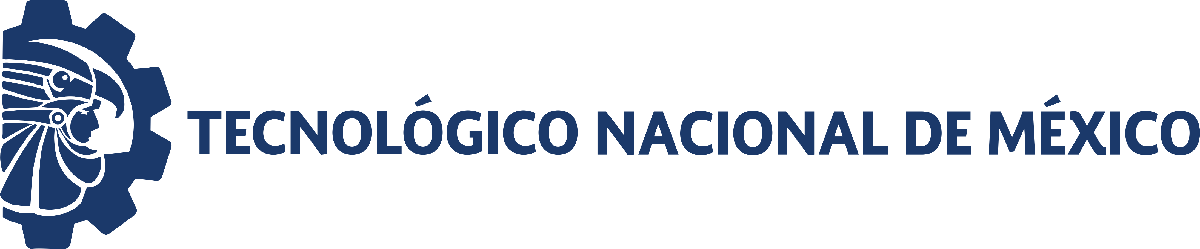                                 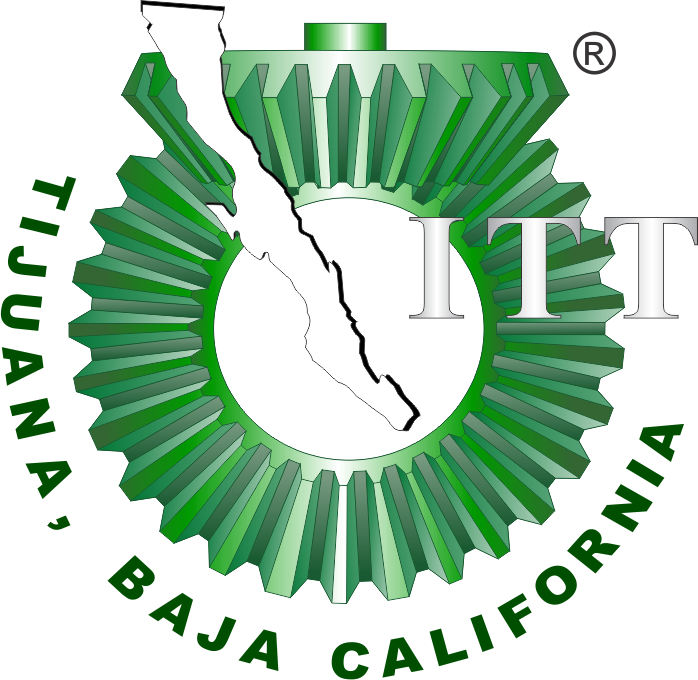

# Práctica 2: Sistema Respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

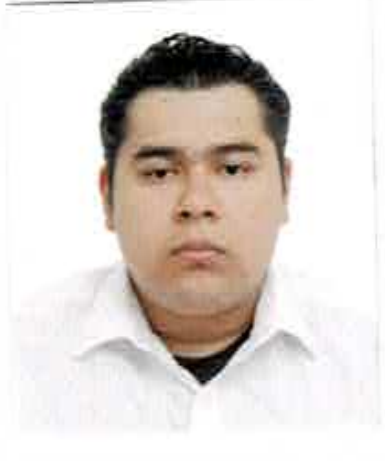

Nombre del alumno: **Mauricio Jesús Meraz Galeana**

Número de control: **18210139**

Correo institucional: **mauricio.meraz18@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'SistemaP2';
open_system(file);
parameters.Solver = 'ode15s';
parameters.Maxstep = '1E-3';
parameters.StopTime = '30';

## Rendimiento del controlador

kP = 151.384

KI = 3438.584

kD =0.496

Rise time = 0.009 s

settling time =0.099 s

Overshoot = 10.5 %

Peak = 1.1 V

## Respuesta a la función sinusoidal : Respiracion normal

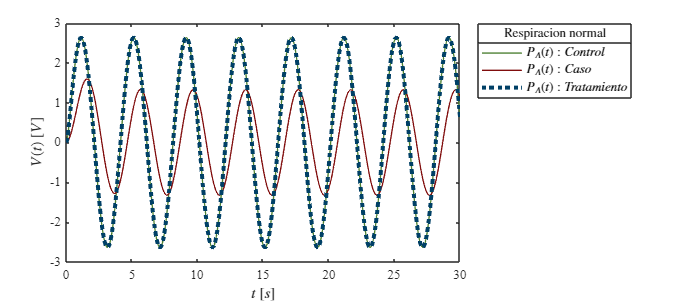

set_param('SistemaP2/Pao(t)','sw','1');
Signal = 'Respiracion normal';
N=sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Respiracion anormal

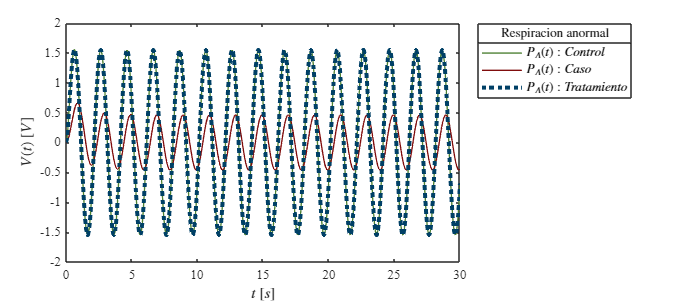

set_param('SistemaP2/Pao(t)','sw','0');
Signal = 'Respiracion anormal';
N=sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Función : Respuesta  a las señales

function plotsignals(t,PAx,PAy,PAz,Signal)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    b11 = [0.5,0.05,0.05];
    grn1 = [0,0.25,0.4];
    gry = [0.3,0.5,0.2];
    hold on; grid off; box on

    plot(t,PAx,'LineWidth',1,'Color',gry)
    plot(t,PAy,'LineWidth',1,'Color',b11)
    plot(t,PAz,':','LineWidth',3,'Color',grn1)
    

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    L = legend('$P_{A}(t):Control $','$P_A(t):Caso$','$P_{A}(t):Tratamiento $');
    set(L,'Interpreter','Latex','FontSize',10,'Location','NorthEastOutside','Box','On')
    title(L,Signal)

    

 if Signal == "Respiración Normal"
        xlim([0,30]); xticks(0:1:30)
        ylim([-3,3]); yticks(-3:0.5:3)
    elseif Signal == "Taquipnea"
        xlim([0,30]); xticks(0:1:30)
        ylim([-3,3]); yticks(-3:0.5:3)
    end
        
        exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
end